# Lab 2: Live script data manipulation of the data collected from ADC

% Setup of conditions (Period T, length of time vector, time vector)
close all; format compact; clc;
ts = 1/1000;
N = length(data);
t = ts*[0:N-1];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Figures %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% -- Figure 2: Plotting time vs. ADC Sample values
adc_samples = [data(:,1) data(:,2)];

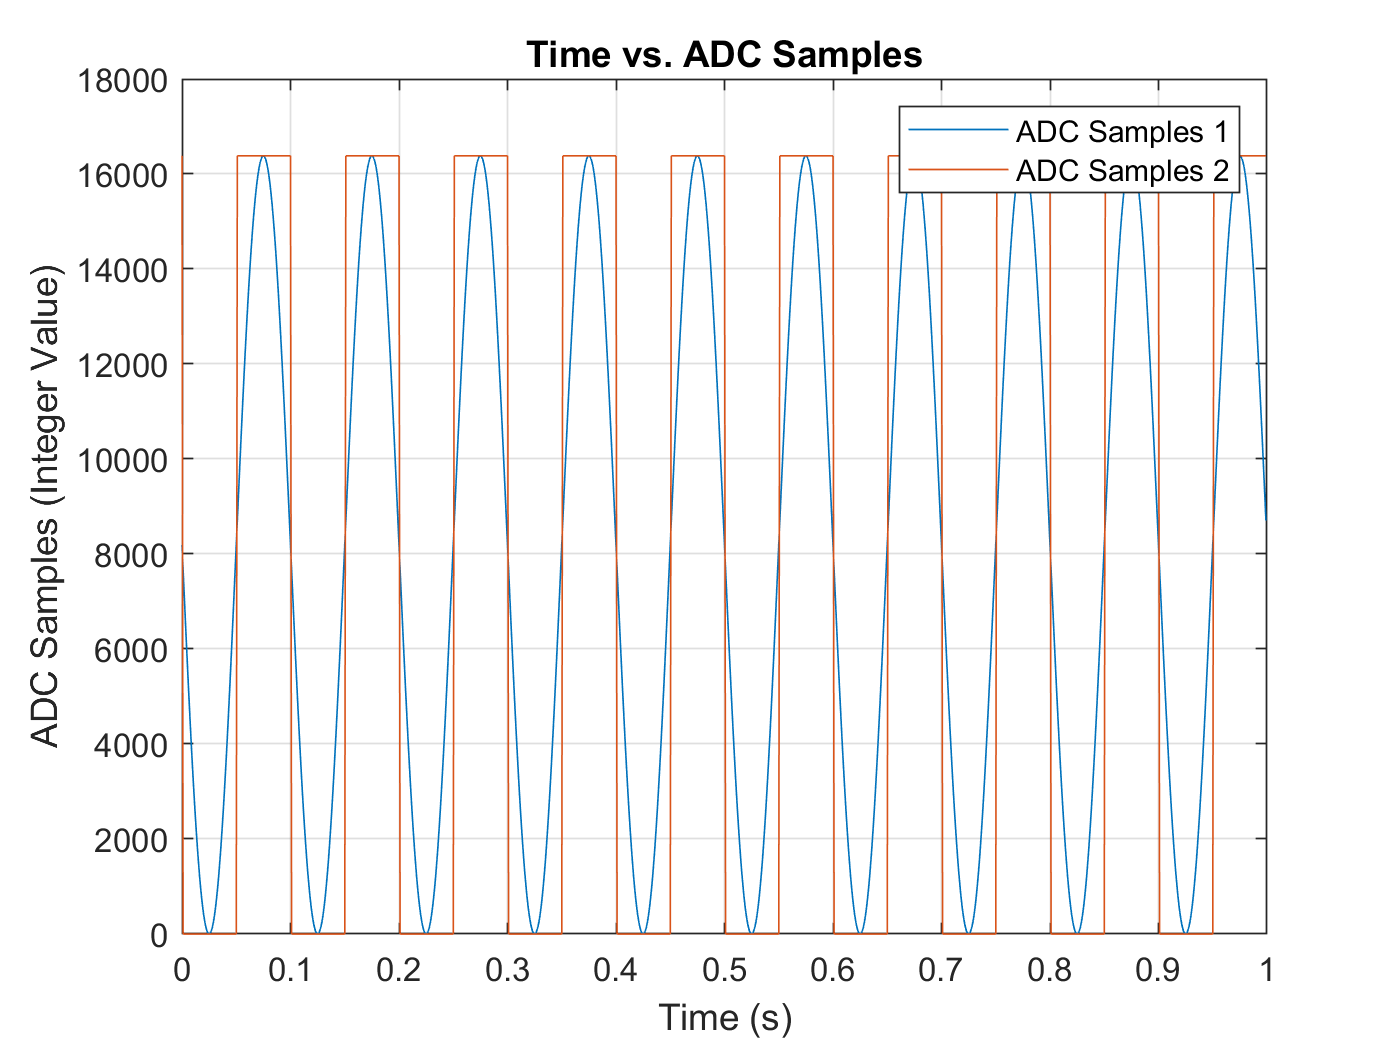

% Create plot of t and adc_samples
h = plot(t,adc_samples,'DisplayName','adc_samples');

% Add xlabel, ylabel, title, and legend
xlabel('t')
ylabel('adc_samples')
title('t vs. adc_samples')
legend
    legend({'ADC Samples 1','ADC Samples 2'})
    title('Time vs. ADC Samples')
    xlabel('Time (s)')
    ylabel('ADC Samples (Integer Value)')
    grid on;
    hold on;


% -- Figure 2: Plotting time vs. voltage samples
figure(2);
voltage_samples = [data(:,3) data(:,4)];

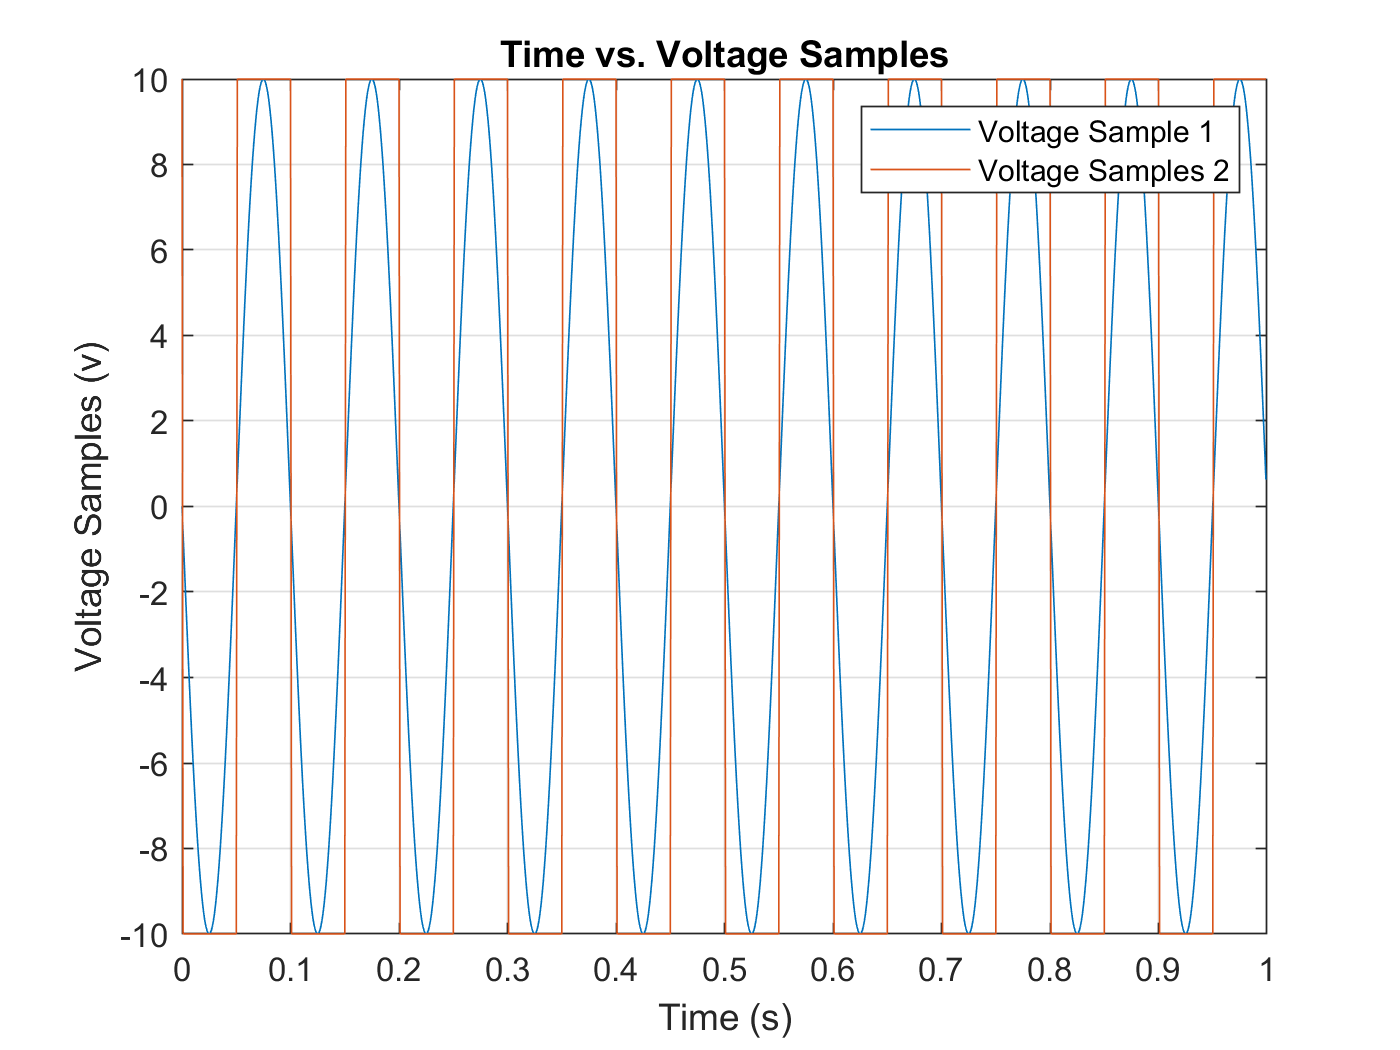

% Create plot of t and voltage_samples
h2 = plot(t,voltage_samples,'DisplayName','voltage_samples');

% Add xlabel, ylabel, title, and legend
xlabel('t')
ylabel('voltage_samples')
title('t vs. voltage_samples')
legend
    legend({'Voltage Sample 1','Voltage Samples 2'})
    title('Time vs. Voltage Samples')
    xlabel('Time (s)')
    ylabel('Voltage Samples (v)')
    grid on;


%%%%%%%%%%%%%%%%%%%%%% Data Manipulation %%%%%%%%%%%%%%%%%%%%%%%%%%

% -- Calculating Min, Max, and Mean for each signal
    
    % -- Mean values
meanADC1 = mean(adc_samples(:,1))

meanADC1 = 8.1915e+03

meanADC2 = mean(adc_samples(:,2))

meanADC2 = 8.1915e+03

meanV1 = mean(voltage_samples(:,1))

meanV1 = 2.5935e-16

meanV2 = mean(voltage_samples(:,2))

meanV2 = 0

    
    % -- Min values
minADC1 = min(adc_samples(:,1))

minADC1 = 0

minADC2 = min(adc_samples(:,2))

minADC2 = 0

minV1 = min(voltage_samples(:,1))

minV1 = -9.9979

minV2 = min(voltage_samples(:,2))

minV2 = -9.9979

   
    % -- Max Values
maxADC1 = max(adc_samples(:,1))

maxADC1 = 16383

maxADC2 = max(adc_samples(:,2))

maxADC2 = 16383

maxV1 = max(voltage_samples(:,1))

maxV1 = 9.9979

maxV2 = max(voltage_samples(:,2))

maxV2 = 9.9979


% -- Calculating frequency of the sine wave of input voltage (Hz)

index = find(voltage_samples(:,1) == maxV1);
    t1 = index(1);
    t2 = index(2);
    t1 = t(t1);
    t2 = t(t2);
freq = 1/(t2 - t1); % Calculation of the frequency
fprintf('The frquency of the signal will be %3.3f Hz\n',freq)

The frquency of the signal will be 10.000 Hz
